## `Задание 1. Свободное движение`

mdl = "task_1";
open_system(mdl);
simIn = Simulink.SimulationInput(mdl);

a0 = 4.5; a1 = 4.5; iy = 1; idy = 0;
out1 = sim(simIn);

a0 = 101.44; a1 = 2.4;
out2 = sim(simIn);

a0 = 100; a1 = 0;
out3 = sim(simIn);

a0 = 101.44; a1 = -2.4; iy = 0.05;
out4 = sim(simIn);

a0 = 4.5; a1 = -4.5;
out5 = sim(simIn);

a0 = -0.64; a1 = 0; iy = 0; idy = 0.1;
out6 = sim(simIn);

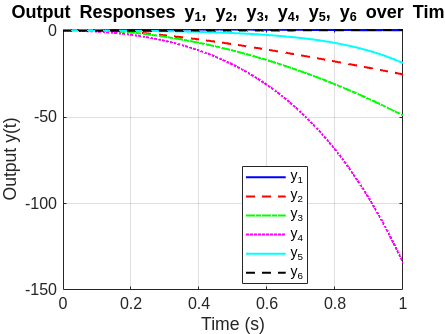

res1 = get(out1, "yout");
res2 = get(out2, "yout");
res3 = get(out3, "yout");
res4 = get(out4, "yout");
res5 = get(out5, "yout");
res6 = get(out6, "yout");

y1 = res1{1}.Values.Data;
y2 = res2{1}.Values.Data;
y3 = res3{1}.Values.Data;
y4 = res4{1}.Values.Data;
y5 = res5{1}.Values.Data;
y6 = res6{1}.Values.Data;

t = out1.tout;  % Время из первой симуляции (можно использовать одно для всех)

% Построение графика
figure;
plot(t, y1, 'b-', 'LineWidth', 1.5); hold on;
plot(t, y2, 'r--', 'LineWidth', 1.5);
plot(t, y3, 'g-.', 'LineWidth', 1.5);
plot(t, y4, 'm:', 'LineWidth', 1.5);
plot(t, y5, 'c-', 'LineWidth', 1.5);
plot(t, y6, 'k--', 'LineWidth', 1.5);
hold off;

% Оформление графика
grid on;
xlabel('Time (s)');
ylabel('Output y(t)');
title('Output Responses y_1, y_2, y_3, y_4, y_5, y_6 over Time');
legend('y_1', 'y_2', 'y_3', 'y_4', 'y_5', 'y_6', 'Location', 'best');
set(gca, 'FontSize', 12);  % Размер шрифта